# Schleifen zum Zählen ("for")

## Einführung und Lernziele

Im vorletzten Kapitel haben wir Schleifen mit Bedingung ("while") kennengelernt, um einzelne Code-Abschnitte zu wiederholen. In der Praxis kommt es oft vor, dass wir von vornherein wissen, wie oft wir eine Handlung wiederholen wollen. Beispielsweise soll in einem Verein darüber abgestimmt werde, ob Anna oder Bob zukünftig die Kasse verwalten soll. Alle Vereinsmitglieder schreiben einen der beiden Namen auf einen Zettel und werfen ihn in die Wahlurne. Jetzt beginnt die Wiederholung. Charlie greift in die Urne, zieht einen Zettel heraus, liest den Namen vor und macht dann entweder bei Anna oder bei Bob einen Strich auf dem Flipboard. Solange Zettel in der Urne sind, wird diese Prozedur wiederholt. Das entspräche der while-Schleife. Wenn wir aber bereits vorher wissen, dass 12 Vereinsmitglieder abgestimmt haben, so wird Charlie 12 x diese Prozedur wiederholen. In diesem Fall bietet sich die Umsetzung als sogenannte **Zählschleife** an.

In diesem MATLAB Live Skript werden wir uns zwei Arten der Zählschleifen erarbeiten:

- Zählschleifen mit explizit definiertem Array

- Zählschleifen mit MATLAB-erzeugten Arrays 

Da die Zählschleifen essentiell von Arrays abhängen, werden wir uns nach der Einführung der ersten Schleifenvariante zunächst mit der MATLAB-Erzeugung von Arrays beschäftigen. Danach werden wir die MATLAB-erzeugten Arrays für Zählschleifen einsetzen und so eine zweite Variante gewinnen, um Zählschleifen zu implementierren. 

## Zählschleife ("for) mit explizit definiertem Array

Bei einer While-Schleife wird ein Anweisungsblock solange wiederholt, bis die dazugehörige Bedingung nicht mehr erfüllt ist. Manchmal möchte man jedoch die Anweisungen auf alle Elemente einer Menge anwenden. Dazu gibt es die **For-Schleife**. Sie hat folgende Syntax:

`for element = Menge`

`    anweisungsblock`

`end`

Es gibt verschiedene Varianten, die Mengen zu beschreiben. Wir betrachten zuerst die Beschreibung der Menge explizit als Array.

Jedes Element der Menge `[2, 6, 8, -1]` soll einzeln angezeigt werden. Das erreicht man durch folgenden Code:

for zahl = [2, 6, 8, -1]
    disp(zahl)
end

Meistens geht es nicht darum, nur etwas einzeln anzuzeigen, sondern die Elemente der Menge zu verarbeiten. Im nächsten Beispiel soll jedes Element der Liste `[4,5,7,11,21]` um `2` erhöht und dann angezeigt werden.

for zahl = [4,5,7,11,21]
    zahl2 = zahl + 2;
    disp(zahl2)
end
disp('Ich bin fertig!');

#### Mini-Übung 1

Schreiben Sie eine For-Schleife mit Array, die die klassischen Schulnoten "sehr gut"  bis "ungenügend" einzeln ausgibt. Zur Erinnerung: die deutschen Schulnotenlauten sehr gut, gut, befriedigend, ausreichend, mangelhaft und ungenügend.

% Hier Ihr Code


#### Mini-Übung 2

Schreiben Sie ein For-Schleife, die nacheinander die Elemente der Menge [1,2,3,4,5,6,7] durch 7 teilt. Lassen Sie die Rechnung mit Ergebnis ausgeben, also z.B. so

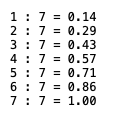

Dabei soll das Ergebnis zwei Nachkommastellen haben.

% Hier Ihr Code


## MATLAB-Methoden zur Erzeugung von Zahlen-Arrays (Vektor und Matrix)

Im Kapitel über Arrays haben wir das Thema bereits vorbereitet. Das händische Erzeugen von Arrays ist nur sinnvoll, wenn es sich um kleine Arrays handelt. Bei großen Arrays liest man beispielsweise Messdaten aus einem Sensor oder einer Excel-Tabelle ein. Sofern es sich um Arrays von Zahlen handelt, die bestimmten Mustern unterliegen, stellt MATLAB verschiedene Methoden zur Erzeugung zur Verfügung. Einige wenige werden wir jetzt hier vorstellen.

### Erzeugungsmethode start : step : stopp für Vektoren

Wenn wir von einer Zahl `start` bis zu einer Zahl `stopp` zählen wollen, bietet MATLAB zur Erzeugung des zugehörigen Vektors den simplem Befehl

`x = start : stopp`

an. Probieren wir es einfach aus und lassen die Zahlen von 1 bis 10 automatisch erzeugen:

x = 1:10;
disp(x)

Wie Sie sehen wird automatisch ein Vektor erzeugt, der eine Zeile und entsprechend viele Spalten (hier 10) hat. Das schauen wir uns noch mit `whos` an:

whos x

In der Überschrift stand jedoch `start : step : stopp`. Also was macht dieses ominöse `step`? Probieren wir es einfach aus.

x = 1 : 2 : 10;
disp(x)

Jetzt wird nur noch jede zweite Zahl erzeugt. Genaugenommen fängt der MATLAB-Interpreter bei 1 an und addiert solange immer wieder 2 dazu, bis MATLAB die maximale Grenze 10 erreicht hat. Würde jetzt zu der 9 noch 2 addiert werden, hätte MATLAB die Grenze überschritten. Daher ist die letzte Zahl im Vektor die 9.

#### Mini-Übung 3

Erzeugen Sie einen Vektor mit 3, 6, 9,  12, ..., 99 und lassen Sie ihn auch ausgeben.

% Hier Ihr Code


Praktischerweise darf `step` auch negativ sein. Dann muss aber auch die erste Zahl `start` größer als die letzte Zahl `stopp` sein, den negatives `step` bedeutet, dass MATLAB rückwärts zählt. Auch hier ein Beispiel, bei der ein Countdown von 10 an rückwärts läuft, bis 0 erreicht ist:

x = 10 : -1 : 0;
disp(x);

### Erzeugungsmethode linspace für Vektoren

Die MATLAB-Funktion `linspace()` wird benutzt, wenn wir in einem Intervall von einer Startzahl `start` bis zu einer Stoppzahl `stopp` gleichmäßig eine bestimmte Anzahl von Zahlen `anzahl` erzeugen wollen:

`x = linspace(start, stopp, anzahl)`

Der folgende Code-Abschnitt erzeugt 11 Zahlen von 0 bis 1:

x = linspace(0, 1, 11);
disp(x);

#### Mini-Übung 4

Erzeugen Sie einen Vektor mit 100 Punkten zwischen -1 und 1 und lassen Sie den Vektor ausgeben.

% Hier Ihr Code


### Erzeugungsmethode zeros und ones für Vektoren und Matrizen

Die folgenden beiden Methoden zur Erzeugung von Zahlen-Arrays sind nicht nur für eindimensionales Arrays (Vektoren), sondern auch für zweidimensionale Arrays (Matrizen) geeignet. Mit den MATLAB-Funktionen zeros und ones erzeugen wir Arrays, die entweder nur mit Nullen oder nur mit Einsen gefüllt sind.  Beim Aufruf wird die Anzahl der Zeilen `m` und die Anzahl der Spalten `n` übergeben, also

- `X = zeros(m,n)`

- `X = ones(m,n)`

Als erstes erzeugen wir eine 5x4-Matrix, die mit Nullen gefüllt ist.

X = zeros(5,4);
disp(X);
whos X

Als nächstes erzeugen wir eine 2x3-Matrix, die mit Einsen gefüllt ist.

X = ones(2,3);
disp(X);
whos X

#### Mini-Übung 5

- Erzeugen Sie zuerst einen Vektor X mit 1 Zeile und 5 Spalten gefüllt mit Einsen. Geben Sie X zur Kontrolle aus. 

- Erzeugen Sie dann einen Vektor Y mit 1 Zeile und 5 Spalten gefüllt mit gleichmäßigem Abstand von 5 bis 10. Geben Sie Y zur Kontrolle aus.

- Schreiben Sie dann eine For-Schleife, die das 1. Element von X und das 1. Element von Y addiert und das Ergebnis ausgibt, dann das 2. Element von X und das 2. Element von Y addiert und ausgibt und das alles wiederholt bis zum jeweils 5. Element.

% Hier Ihr Code


### Erzeugungsmethode randi

Die Erzeugungsmethode `randi()` haben wir bereits kennengelernt. Sie ist der Vollständigkeit hier noch einmal aufgelistet. Zuerst wird das Intervall `[start, stopp]` angegeben, aus dem die ganzzahligen Zufallszahlen gezogen werden. Danach kommt die Anzahl der Zeilen `m` und die Anzahl der Spalten `n`.

`X = randi( [start, stopp], m, n)`

Beispiel: Der folgende Code produziert sechs Zufallszahlen zwischen 1 und 10 in einer 3x2-Matrix:

X = randi( [1, 10], 3, 2);
disp(X);

#### Mini-Übung 6

Erzeugen Sie einen Vektor mit sechs ganzzahligen Lottozahlen zwischen 1 und 49. Lassen Sie dann mit einer For-Schleife den folgenden Text ausgeben:

`Die 1. Lottozahl ist xx.`

`Die 2. Lottozahl ist xx.`

`Die 3. Lottozahl ist xx.`

`Die 4. Lottozahl ist xx.`

`Die 5. Lottozahl ist xx.`

`Die 6. Lottozahl ist xx.`

Dabei soll natürlich xx ersetzt werden durch die 1., 2., 3. usw Lottozahl.

% Hier Ihr Code


## Zählschleife ("for") mit MATLAB-erzeugten Arrays

Nachdem wir nun im obigen Abschnitt uns damit beschäftigt haben, wie Zahlenfolgen automatisch mit MATLAB-Funktionen erzeugt werden, ist es naheliegend, die explizite Angabe der Arrays in For-Schleifen durch die automatisch erzeugten Zahlenfolgen zu ersetzen. Dabei ist die 

`start : step : stopp`

Funktion sicherlich die am meisten genutzte Funktion in For-Schleifen, also

`for i = start : step : stopp `

`    anweisungsblock`

`end`

wobei step auch weggelassen werden darf, sofern wir immer +1 addieren.

Hier ein Beispiel von 1 bis 100:

for zahl = 1 : 100
    disp(zahl)
end
disp('Fertig!')

Jetzt geben wir die ungeraden Zahlen von 3 bis 13 aus:

for zahl = 3 : 2 : 13
    disp(zahl)
end
disp('Fertig!')

Durch Angabe einer negativen Schrittweite kann auch rückwärts gezählt werden:

for zahl = 13 : -2 : 3
    disp(zahl)
end
disp('Fertig!')

Auch wenn die `start : step : stopp` Methode sicherlich die häufigste ist, können wir auch die anderen Methoden nutzen. Der folgende Code erstellt zum Beispiel eine Wertetabelle für die quadratische Funktion $f(x)=x^2$ im Intervall $[0,1]$:

for x = linspace(0, 1, 11)
    y = x^2;
    fprintf('f(%.2f) = %.2f \n', x, y);
end

#### Mini-Übung 7

Schreiben Sie fünf for-Schleifen, die folgendermaßen zählen:

- 3 bis 13

- -4 bis 4

- alle geraden Zahlen von 20 bis 30

- jede fünfte Zahl von -100 bis -60

- von 100 rückwärts bis 1

Geben Sie die Zahlen auch jeweils aus.

% Hier Ihr Code


Bis jetzt haben wir die Elemente der Menge mit der disp()-Funktion angezeigt, aber natürlich können wir damit auch weitere Daten verarbeiten. Das folgende Programm zeigt beispielsweise, wie man so die Summe der ersten 100 Zahlen berechnen kann.

summe = 0;
for i = 1:100
    summe = summe + i;
end
fprintf('Die Summe von 1 bis 100 ist %d.', summe);

For-Schleifen können auch ineinander verschachtelt werden. Das ist z.B. hilfreich, wenn man alle Paare durch Kombination bilden will.

Hinweis: Es ist auch möglich, einen String in die `fprintf()`-Funktion einzusetzen. Der dazugehörige Platzhalter heißt `%s`.

for i = ["rot", "grün", "blau"]
    for j = [1, 2, 5]
        fprintf('Farbe: %s \t| Zahl: %d \n', i, j);
    end
end

Natürlich kann eine for- auch mit einer if-else-Konstruktion kombiniert werden. Was vermuten Sie, macht folgender Code-Schnipsel? Stellen Sie erst eine Vermutung auf und lassen Sie dann den Code in der Code-Zelle ausführen.

% Erzeugung Array
zahlen = randi( [1,100], 1, 25);

% Verarbeitung
for z = zahlen 
    if (1 <= z) && (z <= 49)
        fprintf('%d ist eine Lottozahl.\n', z);
    else
        fprintf('%d ist KEINE Lottozahl.\n', z);
    end
end

Das folgende Beispiel zeigt, wie man eine input-Abfrage mit for kombinieren kann. Beipielsweise soll das Programm fragen, wie oft das Wort Hallo angezeigt werden soll:

% Eingabe
anzahl = input('Wie oft soll ich Hallo anzeigen?');

% Verarbeitung und Ausgabe
for i = 1 : anzahl
    disp('Hallo');
end

#### Mini-Übung 8

Schreiben Sie ein Skript mit einer For-Schleife, das die Quadratzahlen der Zahlen 1 bis 20 ausgibt. Die Ausgabe solte folgendermaßen aussehen:

`Die Quadratzahl von 1 ist 1.`

`Die Quadratzahl von 2 ist 4.`

`Die Quadratzahl von 3 ist 9.`

`usw.`

% Hier Ihr Code:


## Zusammenfassung

Letzten Endes haben wir nun alle Programmierkonstrukte kennengelernt, die man für alltägliche Skripte braucht. In den vorangegangen MATLAB Live Skripten haben wir das EVA-Prinzip mit der Umsetzung in MATLAB über 

- Eingabe: `input()`

- Verarbeitung: Variablen und Datentypen (`Integer, Float, String, Bool, Array`)

- Ausgabe: `disp()` und `fprintf()`

behandelt. Danach haben wir uns verschiedenen Kontrollstrukturen gewidmet, um Programmcode nicht mehr nur linear ausführen zu lassen. Das waren im Einzelnen

- Vergleiche, Bedingungen sowie digitale Logik (UND, ODER, NICHT),

- Programmverzweigungen (`if - elseif - else`),

- Schleifen mit Bedingungen (`while`) und

- Zählschleifen (`for`).

Eine fortgeschrittene Technik, die sogenannten Funktionen, werden wir im nächsten MATLAB Live Skript kennenlernen. 

## Lösungen zu den Mini-Übungen

**Lösung zu Mini-Übung 1**

Schreiben Sie eine For-Schleife mit Array, die die klassischen Schulnoten "sehr gut"  bis "mangelhaft" einzeln ausgibt.

% Erzeugung Array
noten = ["sehr gut","gut", "befriedigend", "ausreichend", "mangelhaft", "ungenügend"];

% Ausgabe Array
for note = noten
    disp(note);
end

**Lösung zu Mini-Übung 2**

Schreiben Sie ein For-Schleife, die nacheinander die Elemente der Menge [1,2,3,4,5,6,7] durch 7 teilt. Lassen Sie die Rechnung mit Ergebnis ausgeben, also z.B. so

Dabei soll das Ergebnis zwei Nachkommastellen haben.

% Ausgabe 
for zahl = [1,2,3,4,5,6,7]
    fprintf('%g : %g = %.2f \n', zahl, 7, zahl / 7);
end

**Lösung zu Mini-Übung 3**

Erzeugen Sie ein Array mit 3, 6, 9,  12, ..., 99 und lassen Sie es ausgeben.

% Eingabe Array
x = 3 : 3 : 99;

% Ausgabe
disp(x);

**Lösung zu Mini-Übung 4**

Erzeugen Sie ein eindimensionales Array mit 100 Punkten zwischen -1 und 1 und lassen Sie das Array ausgeben.

% Eingabe Array
x = linspace(-1, 1, 100);

% Ausgabe
disp(x);

**Lösung zu Mini-Übung 5**

- Erzeugen Sie zuerst ein eindimensionales Array X mit 1 Zeile und 5 Spalten gefüllt mit Einsen. Geben Sie X zur Kontrolle aus. 

- Erzeugen Sie dann ein eindimensionales Array Y mit 1 Zeile und 5 Spalten gefüllt mit gleichmäßigem Abstand von 5 bis 10. Geben Sie Y zur Kontrolle aus.

- Schreiben Sie dann eine For-Schleife, die das 1. Element von X und das 1. Element von Y addiert und das Ergebnis ausgibt, dann das 2. Element von X und das 2. Element von Y addiert und ausgibt und das alles wiederholt bis zum jeweils 5. Element.

% Erzeugung und Ausgabe von X 
X = ones(1,5);
disp(X)

% Erzeugung und Ausgabe von Y 
Y = linspace(5, 10, 5);
disp(Y)

% For-Schleife mit Addition und Ausgabe des jeweils i-ten Elements
for i = [1,2,3,4,5]
    x = X(i);
    y = Y(i);
    fprintf('%d + %.2f = %d \n', x, y, x+y);
end


**Lösung zu Mini-Übung 6**

Erzeugen Sie ein eindimensionales Array mit sechs ganzzahligen Lottozahlen zwischen 1 und 49. Lassen Sie dann mit einer For-Schleife den folgenden Text ausgeben:

`Die 1. Lottozahl ist xx.`

`Die 2. Lottozahl ist xx.`

`Die 3. Lottozahl ist xx.`

`Die 4. Lottozahl ist xx.`

`Die 5. Lottozahl ist xx.`

`Die 6. Lottozahl ist xx.`

Dabei soll natürlich xx ersetzt werden durch die 1., 2., 3. usw Lottozahl.

% Erzeugung Lottozahlen
lottozahlen = randi( [1, 49], 1, 6);

% Ausgabe
for i = [1, 2, 3, 4, 5, 6]
    fprintf('Die %d. Lottozahl ist %d. \n', i, lottozahlen(1,i));
end


**Lösung zu Mini-Übung 7**

Schreiben Sie fünf for-Schleifen, die folgendermaßen zählen:

- 3 bis 13

- -4 bis 4

- alle geraden Zahlen von 20 bis 30

- jede fünfte Zahl von -100 bis -60

- von 100 rückwärts bis 1

Geben Sie die Zahlen auch jeweils aus.

% 3 bis 13
for zahl1 = 3 : 13
    disp(zahl1);
end

% -4 bis 4
for zahl2 = -4 : 4
    disp(zahl2);
end

% alle geraden Zahlen von 20 bis 30
for zahl3 = 20 : 2 : 30
    disp(zahl3);
end

% jede fünfte Zahl von -100 bis -60
for zahl4 = -100 : 5: -60
    disp(zahl4);
end

% von 100 rückwärts bis 1
for zahl5 = 100 : -1 : 1
    disp(zahl5);
end

**Lösung zu Mini-Übung 8**

Schreiben Sie ein Skript mit einer For-Schleife, das die Quadratzahlen der Zahlen 1 bis 20 ausgibt. Die Ausgabe solte folgendermaßen aussehen:

`Die Quadratzahl von 1 ist 1.`

`Die Quadratzahl von 2 ist 4.`

`Die Quadratzahl von 3 ist 9.`

`usw.`

% Ausgabe
for i = 1:20
    fprintf('Die Quadratzahl von %d ist %d.\n', i, i^2);
end
